# **Mobile Rover Localization**

This is the localization script that will help determine the orientation and location of the rover within the arena. Additionally, it will determine the location of the target within the arena.

## Step 1: Prepare the MATLAB Workspace 

Before we start anything, let's clear the command window, clear any previous images, close any open figures and load the calibration data.

clear;
close all;
clc;
load color.mat;
load orthoCalibrationData.mat;
load offsetCalibrationRover.mat;
load offsetCalibrationTarget.mat;

## **Step 2: Enter the arena's dimensions and calculate conversion factor**

Let's also ensure that we calculate a conversion factor from pixels to cms (this will be used later) and **set the arena dimensions.**

% Arena dimensions in centimeters
arenaHeight= 75;
arenaWidth = 75;

% Calculate the conversion factor to change between pixels and centimeters
arenaWidthPx = max(newCorners(:,1)) - min(newCorners(:,1));
arenaHeightPx = max(newCorners(:,2)) - min(newCorners(:,2));
cmsPerPxHeight = arenaHeight/arenaHeightPx;
cmsPerPxWidth = arenaWidth/arenaWidthPx;

% Package the scaling factors into a vector
cmsPerPx = [cmsPerPxWidth, cmsPerPxHeight];

## **Step 3: Initialize the webcam**

Now let's initialize the webcam.** Use the Automatic suggestion to enter your webcam in cam variable.**

% Initialize the webcam
cam = webcam("USB2.0 PC CAMERA");
preview(cam);
response = 'no';
while ~strcmpi(response,'yes')
    response = input('Once you can see the entire arena and the rover in the preview, please enter "yes": \n','s');
    clc;
end
closePreview(cam);

## Step 4a: Get the location and heading of the rover

Once the camera feed has been established, we will use the rover's calibration data to determine the location of the rover within the image. **Please ensure that the rover and target are located in different areas within the arena before running this section.**

% Take a snapshot
im = snapshot(cam);

% Translate the image to the orthogonal view (Top View)
orthoViewRover = im2orthoview(im,tform,outputView, outputSize);

% Determine the coordinates for the center of the colored disk without corrections
% and the rover's heading (its orientation)
[discCenterX, discCenterY, heading] = roverPosAng(orthoViewRover,P)

discCenterX = 427.8696

discCenterY = 247.6636

heading = 1.7287


% Determine the coordinates of the rover's center while incorporating offset values in cm's
[cmPlate(1), cmPlate(2)] = getLocation(discCenterX, discCenterY, newCorners,...
    horzOffsetRange, verticalOffsetRange, arenaHeight, cmsPerPx);

## Step 4b: Get the location of the target      

We will also use the calibration data for the target to determine its location in the image. 

% Determine the coordinates for the center of the target without corrections
[targetCenterX, targetCenterY] = targetPos(orthoViewRover, newCorners);

% Determine the coordinates for the center of the target while incorporating offset values in cm's
[cmTarget(1), cmTarget(2)] = getLocation(targetCenterX, targetCenterY, newCorners,...
    horzOffsetRangeTarget, verticalOffsetRangeTarget, arenaHeight, cmsPerPx);

## Step 5: Visualize the results

Once we have the location and heading information for the rover, we can visualize the results by plotting it on top of the image from the webcam. 

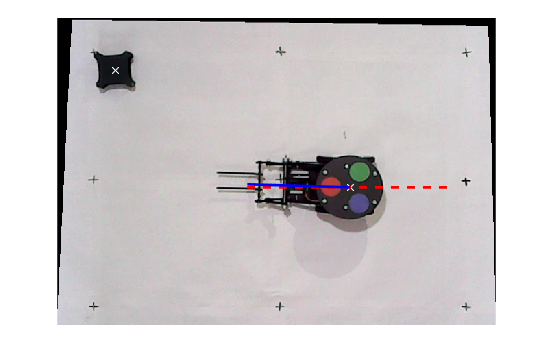

% Set the points to draw the lines for the heading and the center of the rover
L=150;
thXE = discCenterX - L*cosd(heading);
thYE = discCenterY - L*sind(heading);

% Display the orthogonal view of the arena
imshow(orthoViewRover);
hold on;

% Display the center of the rover and the target in the image
plot(discCenterX,discCenterY,'wx');
plot(targetCenterX, targetCenterY, 'wx');

% Display the heading (angular orientation) of the rover in the image
plot(discCenterX + [-L L], [discCenterY discCenterY],'r--','LineWidth',2);
plot([discCenterX thXE], [discCenterY thYE],'b','LineWidth',2);

*Copyright 2018 - 2020 The MathWorks, Inc.*